load("qcmVariables.mat");
outputList = ["Vehicle Displacement","Vehicle Velocity","Suspension Displacement","Suspension Velocity"];

#### Let us examine how changing sampling time impacts fit and computational cost. 

#### We will select an input velocity of 10 kmph for all the samples

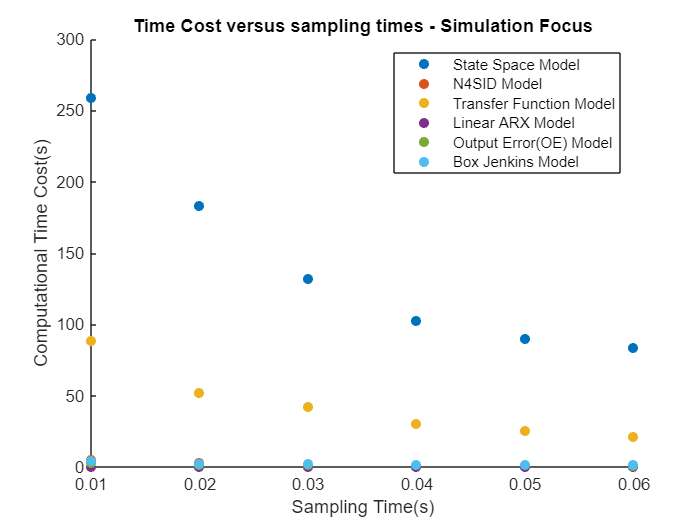

time_sim = figure;
scatter(sampTimeRange(:),timeCostArray(:,10,1,1),'filled');
xlabel("Sampling Time(s)");
ylabel("Computational Time Cost(s)");
title("Time Cost versus sampling times - Simulation Focus");
hold on;
scatter(sampTimeRange(:),timeCostArray(:,10,1,2),'filled');
scatter(sampTimeRange(:),timeCostArray(:,10,1,3),'filled');
scatter(sampTimeRange(:),timeCostArray(:,10,1,4),'filled');
scatter(sampTimeRange(:),timeCostArray(:,10,1,5),'filled');
scatter(sampTimeRange(:),timeCostArray(:,10,1,6),'filled');
legend("State Space Model", "N4SID Model","Transfer Function Model","Linear ARX Model","Output Error(OE) Model","Box Jenkins Model");
hold off;

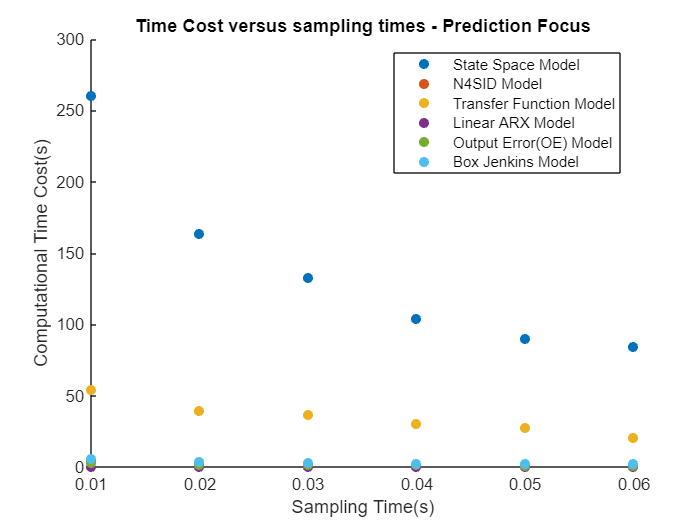

time_pred = figure;
scatter(sampTimeRange(:),timeCostArray(:,10,2,1),'filled');
xlabel("Sampling Time(s)");
ylabel("Computational Time Cost(s)");
title("Time Cost versus sampling times - Prediction Focus");
hold on;
scatter(sampTimeRange(:),timeCostArray(:,10,2,2),'filled');
scatter(sampTimeRange(:),timeCostArray(:,10,2,3),'filled');
scatter(sampTimeRange(:),timeCostArray(:,10,2,4),'filled');
scatter(sampTimeRange(:),timeCostArray(:,10,2,5),'filled');
scatter(sampTimeRange(:),timeCostArray(:,10,2,6),'filled');
legend("State Space Model", "N4SID Model","Transfer Function Model","Linear ARX Model","Output Error(OE) Model","Box Jenkins Model");
hold off;

The above plots support intuitive reasoning that the more the number of samples, the longer it takes to compute a fitting model. While the relative trends between estimation models remains same for both simulation and prediction focus, it is interesting to note that the Transfer function model seems to perform faster on prediction mode. This observation could be simply a computational deviation and must be validated against the velocity sweep for confirmation.

#### Now, it's time to test whether the sampling time affects estimation model fit. Once again, we will select the input velocity of 10 kmph and compare various model fits against validation data

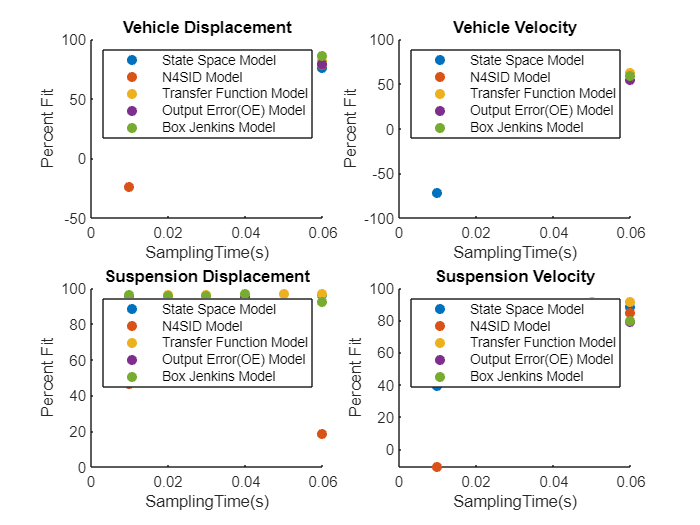

fit_sim = figure;
for j = 1:4

    subplot(2,2,j);
    scatter(sampTimeRange, avgFitArraySB(:,10,1,1,j),'filled');
    title(outputList(j));
    xlabel("SamplingTime(s)");
    ylabel("Percent Fit");
    %title("Sampling Time versus Model Fit on Val data - Simulation Focus");
    hold on;
    scatter(sampTimeRange, avgFitArraySB(:,10,1,2,j),'filled');
    scatter(sampTimeRange, avgFitArraySB(:,10,1,3,j),'filled');
    %scatter(sampTimeRange, avgFitArraySB(:,10,1,4,j),'filled');
    scatter(sampTimeRange, avgFitArraySB(:,10,1,5,j),'filled');
    scatter(sampTimeRange, avgFitArraySB(:,10,1,6,j),'filled');
    %legend("State Space Model", "N4SID Model","Transfer Function Model","Linear ARX Model","Output Error(OE) Model","Box Jenkins Model");
    legend("State Space Model", "N4SID Model","Transfer Function Model","Output Error(OE) Model","Box Jenkins Model");
    hold off;
end

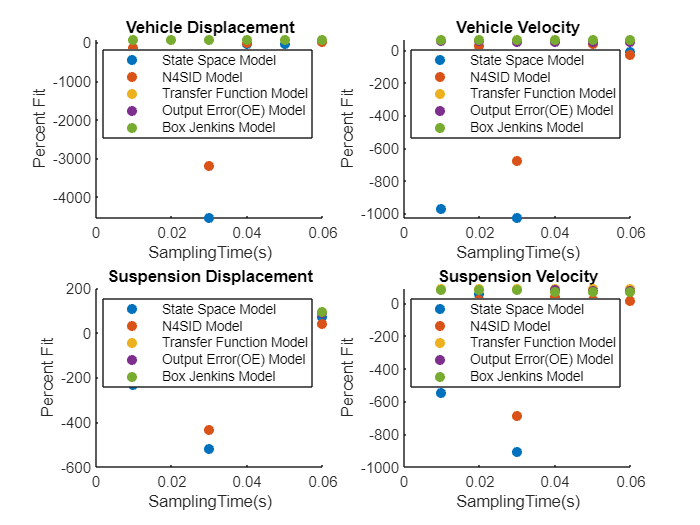

fit_pred = figure;
for j = 1:4

    subplot(2,2,j);
    scatter(sampTimeRange, avgFitArraySB(:,10,2,1,j),'filled');
    title(outputList(j));
    xlabel("SamplingTime(s)");
    ylabel("Percent Fit");
    %title("Sampling Time versus Model Fit on Val data - Prediction Focus");
    hold on;
    scatter(sampTimeRange, avgFitArraySB(:,10,2,2,j),'filled');
    scatter(sampTimeRange, avgFitArraySB(:,10,2,3,j),'filled');
    %scatter(sampTimeRange, avgFitArraySB(:,10,2,4,j),'filled');
    scatter(sampTimeRange, avgFitArraySB(:,10,2,5,j),'filled');
    scatter(sampTimeRange, avgFitArraySB(:,10,2,6,j),'filled');
    %legend("State Space Model", "N4SID Model","Transfer Function Model","Linear ARX Model","Output Error(OE) Model","Box Jenkins Model");
    legend("State Space Model", "N4SID Model","Transfer Function Model","Output Error(OE) Model","Box Jenkins Model");
    hold off;
end

These two plots reveal some interesting observations. Box Jenkins Model, Output Error Model and Transfer Function Model appear not to be quite impacted by reducing number of samples as the sampling time goes up from 0.01s to 0.06s. It's important to note that 0.07s, the state space model of the Quarter Car Model yields an unstable system so we stop iterating at 0.06s. On the other hand, N4SID and SSEST models display peak fit values at neither 0.01s or 0.06s but at 0.02s. This behavior is certainly curious and requires in-depth investigation.

The prediction focus plot is biased by the poor fit values generated by the N4SID and SSEST models while the polynomial models perform comfortably in their default setting. 

#### Now, let us see the performance of the models against unseen step response data

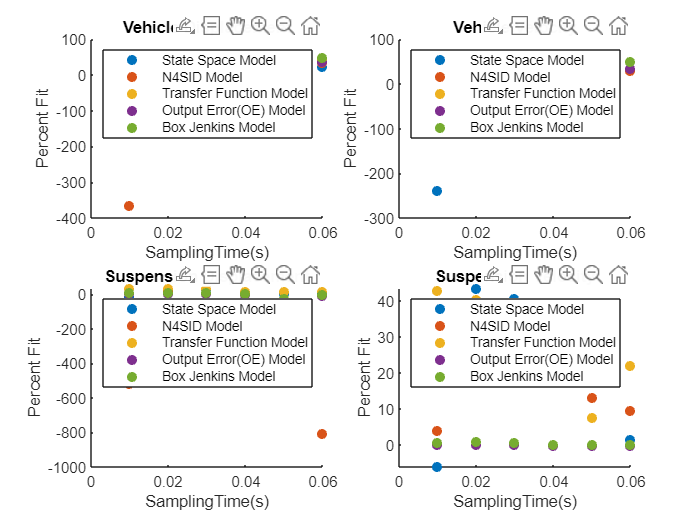

fit_step_sim = figure;
for j = 1:4

    subplot(2,2,j);
    scatter(sampTimeRange, avgFitArrayStep(:,10,1,1,j),'filled');
    title(outputList(j));
    xlabel("SamplingTime(s)");
    ylabel("Percent Fit");
    %title("Sampling Time versus Model Fit on Step Val data - Simulation Focus");
    hold on;
    scatter(sampTimeRange, avgFitArrayStep(:,10,1,2,j),'filled');
    scatter(sampTimeRange, avgFitArrayStep(:,10,1,3,j),'filled');
    %scatter(sampTimeRange, avgFitArrayStep(:,10,1,4,j),'filled');
    scatter(sampTimeRange, avgFitArrayStep(:,10,1,5,j),'filled');
    scatter(sampTimeRange, avgFitArrayStep(:,10,1,6,j),'filled');
    %legend("State Space Model", "N4SID Model","Transfer Function Model","Linear ARX Model","Output Error(OE) Model","Box Jenkins Model");
    legend("State Space Model", "N4SID Model","Transfer Function Model","Output Error(OE) Model","Box Jenkins Model");
    hold off;
end

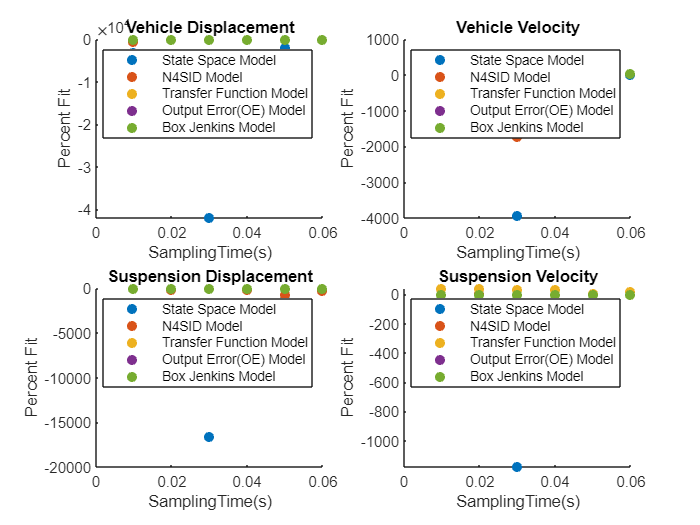

fit_step_pred = figure;
for jtr = 1:4

    subplot(2,2,jtr);
    scatter(sampTimeRange, avgFitArrayStep(:,10,2,1,jtr),'filled');
    title(outputList(jtr));
    xlabel("SamplingTime(s)");
    ylabel("Percent Fit");
    %title("Sampling Time versus Model Fit on Step Val data - Prediction Focus");
    hold on;
    scatter(sampTimeRange, avgFitArrayStep(:,10,2,2,jtr),'filled');
    scatter(sampTimeRange, avgFitArrayStep(:,10,2,3,jtr),'filled');
    %scatter(sampTimeRange, avgFitArrayStep(:,10,2,4,jtr),'filled');
    scatter(sampTimeRange, avgFitArrayStep(:,10,2,5,jtr),'filled');
    scatter(sampTimeRange, avgFitArrayStep(:,10,2,6,jtr),'filled');
    %legend("State Space Model", "N4SID Model","Transfer Function Model","Linear ARX Model","Output Error(OE) Model","Box Jenkins Model");
    legend("State Space Model", "N4SID Model","Transfer Function Model","Output Error(OE) Model","Box Jenkins Model");
    hold off;
end

The plots of model fit against unseen data corroborate the trends we noticed in the validation against seen input type. However, the fit against unseen input type is clearly worse than the performance against a seen input type, thus indicating that the models do not generalize well.

#### Next, we will see if the velocity profile changes will contribute to any impact on the fit and time cost. This time we will freeze the sampling time at 0.05s

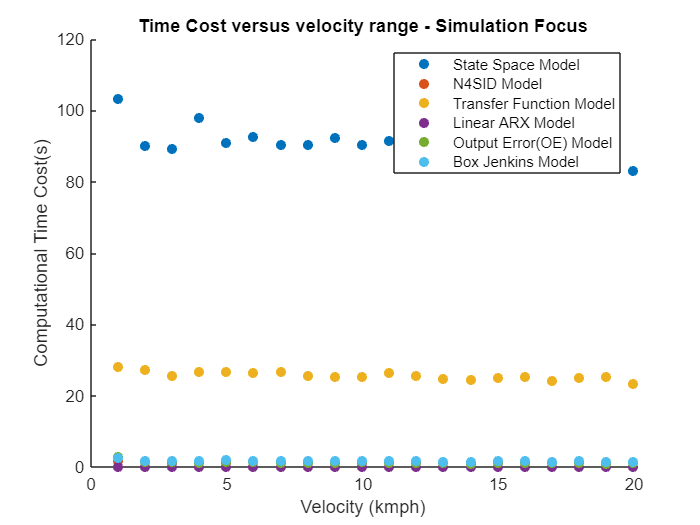

time_vel_sim = figure;
scatter(velRange(:),timeCostArray(5,:,1,1),'filled');
xlabel("Velocity (kmph)");
ylabel("Computational Time Cost(s)");
title("Time Cost versus velocity range - Simulation Focus");
hold on;
scatter(velRange(:),timeCostArray(5,:,1,2),'filled');
scatter(velRange(:),timeCostArray(5,:,1,3),'filled');
scatter(velRange(:),timeCostArray(5,:,1,4),'filled');
scatter(velRange(:),timeCostArray(5,:,1,5),'filled');
scatter(velRange(:),timeCostArray(5,:,1,6),'filled');
legend("State Space Model", "N4SID Model","Transfer Function Model","Linear ARX Model","Output Error(OE) Model","Box Jenkins Model");
hold off;

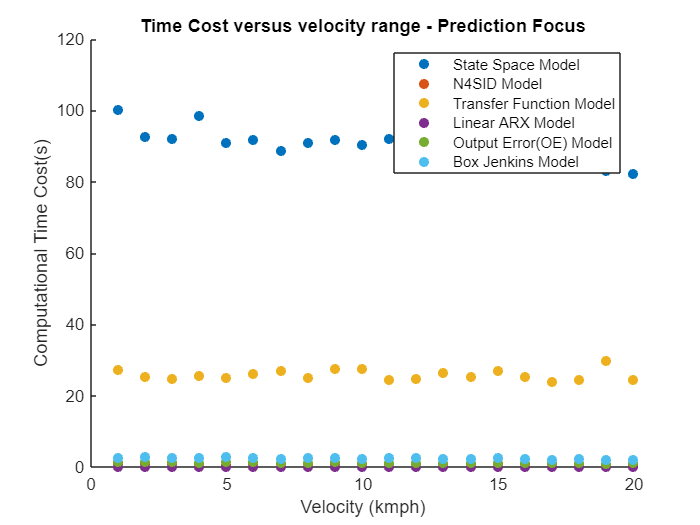

time_vel_pred = figure;
scatter(velRange(:),timeCostArray(5,:,2,1),'filled');
xlabel("Velocity (kmph)");
ylabel("Computational Time Cost(s)");
title("Time Cost versus velocity range - Prediction Focus");
hold on;
scatter(velRange(:),timeCostArray(5,:,2,2),'filled');
scatter(velRange(:),timeCostArray(5,:,2,3),'filled');
scatter(velRange(:),timeCostArray(5,:,2,4),'filled');
scatter(velRange(:),timeCostArray(5,:,2,5),'filled');
scatter(velRange(:),timeCostArray(5,:,2,6),'filled');
legend("State Space Model", "N4SID Model","Transfer Function Model","Linear ARX Model","Output Error(OE) Model","Box Jenkins Model");
hold off;

As expected, there is no apparent impact of varying input velocity on the estimation time cost. Let's find out if a similar statement is true for model fit.

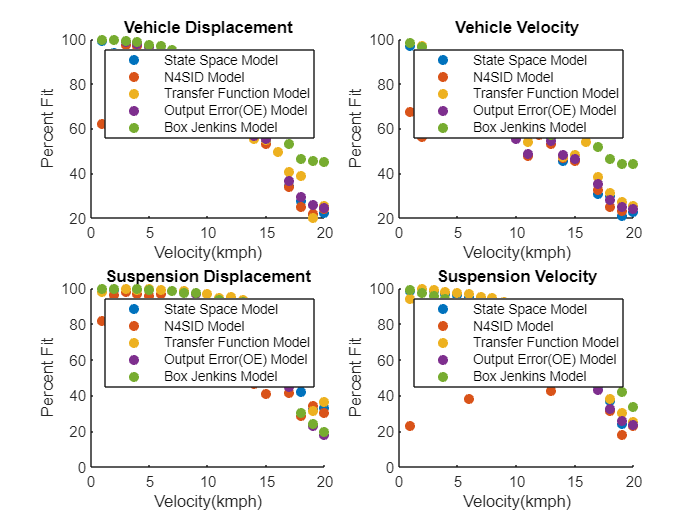

fit_vel_sim = figure;
for itr = 1:4

    subplot(2,2,itr);
    scatter(velRange, avgFitArraySB(5,:,1,1,itr),'filled');
    title(outputList(itr));
    xlabel("Velocity(kmph)");
    ylabel("Percent Fit");
    %title("Model Fit versus velocity range on Val data - Simulation Focus");
    hold on;
    scatter(velRange, avgFitArraySB(5,:,1,2,itr),'filled');
    scatter(velRange, avgFitArraySB(5,:,1,3,itr),'filled');
    %scatter(velRange, avgFitArraySB(5,:,1,4,itr),'filled');
    scatter(velRange, avgFitArraySB(5,:,1,5,itr),'filled');
    scatter(velRange, avgFitArraySB(5,:,1,6,itr),'filled');
    %legend("State Space Model", "N4SID Model","Transfer Function Model","Linear ARX Model","Output Error(OE) Model","Box Jenkins Model");
    legend("State Space Model", "N4SID Model","Transfer Function Model","Output Error(OE) Model","Box Jenkins Model");
    hold off;
end

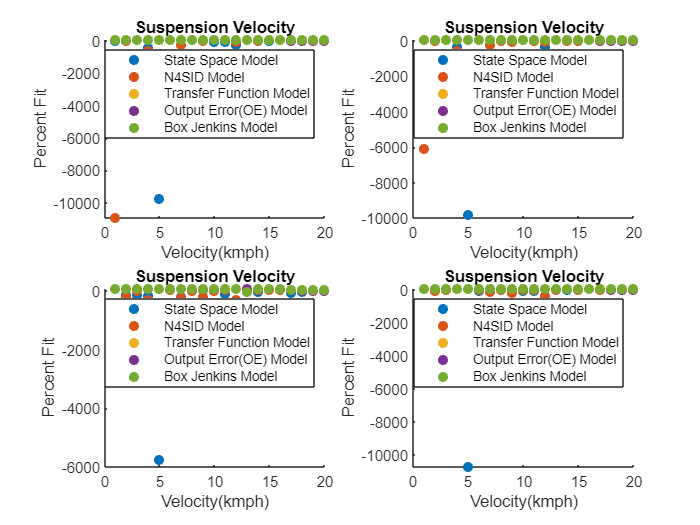

fit_vel_pred = figure;
for itr = 1:4

    subplot(2,2,itr);
    scatter(velRange, avgFitArraySB(5,:,2,1,itr),'filled');
    title(outputList(itr));
    xlabel("Velocity(kmph)");
    ylabel("Percent Fit");
    %title("Model Fit versus velocity range on Val data - Prediction Focus");
    hold on;
    scatter(velRange, avgFitArraySB(5,:,2,2,itr),'filled');
    scatter(velRange, avgFitArraySB(5,:,2,3,itr),'filled');
    %scatter(velRange, avgFitArraySB(5,:,2,4,itr),'filled');
    scatter(velRange, avgFitArraySB(5,:,2,5,itr),'filled');
    scatter(velRange, avgFitArraySB(5,:,2,6,itr),'filled');
    %legend("State Space Model", "N4SID Model","Transfer Function Model","Linear ARX Model","Output Error(OE) Model","Box Jenkins Model");
    legend("State Space Model", "N4SID Model","Transfer Function Model","Output Error(OE) Model","Box Jenkins Model");
    hold off;
end

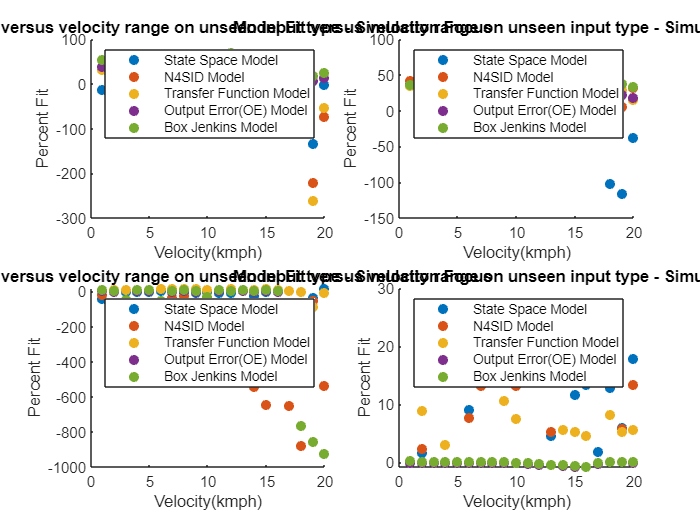

fit_vel__step_sim = figure;
for itr = 1:4

    subplot(2,2,itr);
    scatter(velRange, avgFitArrayStep(5,:,1,1,itr),'filled');
    title(outputList(j));
    xlabel("Velocity(kmph)");
    ylabel("Percent Fit");
    %title("Model Fit versus velocity range on unseen input type - Simulation Focus");
    hold on;
    scatter(velRange, avgFitArrayStep(5,:,1,2,itr),'filled');
    scatter(velRange, avgFitArrayStep(5,:,1,3,itr),'filled');
    %scatter(velRange, avgFitArrayStep(5,:,1,4,itr),'filled');
    scatter(velRange, avgFitArrayStep(5,:,1,5,itr),'filled');
    scatter(velRange, avgFitArrayStep(5,:,1,6,itr),'filled');
    %legend("State Space Model", "N4SID Model","Transfer Function Model","Linear ARX Model","Output Error(OE) Model","Box Jenkins Model");
    legend("State Space Model", "N4SID Model","Transfer Function Model","Output Error(OE) Model","Box Jenkins Model");
    hold off;
end